#### **Question:**

Suppose the difference equation of a system is given as follows:

*y*[*n*] = 1.25*y*[*n*-1] – 0.78125*y*[*n*-2] + *x*[*n*] +2*x*[*n*-1] + *x*[*n*-2]

Let the sampling frequency is 10 kHz. 

**Answer:**

clc; close all; clear all;
% Q.2.1: Transfer function, Pole-zero and BW
%y[n]=1.25y[n-1]-0.78125y[n-2]+x[n]+2x[n-1]+x[n-2]
b= [1 2 1];
a = [1 -1.25 0.78125];              % coefficients 

**(a)** Determine the transfer function of the filter

H= tf(b,a,1/10^4,'variable','z^-1') % Transfer function 

H =
 
       1 + 2 z^-1 + z^-2
  ---------------------------
  1 - 1.25 z^-1 + 0.7813 z^-2
 
Sample time: 0.0001 seconds
Discrete-time transfer function.



**(b)** Determine the poles and zeroes of the filter

[zero,pole] = tf2zp(b,a)            % Obtain zero-pole-gain

zero =     -1
    -1


pole =    0.6250 + 0.6250i
   0.6250 - 0.6250i


**(d)** Determine the Passband bandwidth (BW) of the filter  (*Hint: For second-order IIR filters, the bandwidth of the passband can be approximated using the following formulation *$\Delta \hat{\omega} \approx 2\frac{\left|1-r\right|}{\sqrt{r}}$ , *where r is the distance of the pole from the origin.*)

a=abs(pole)';
r=a(:,1);                           % Distance of pole from the origin
BWn=2*(abs(1-r)./sqrt(r));          %normalized BW of the filter
Fs=10000;
BWf=(Fs/(2*pi))*BWn

BWf = 393.1395

**(e)** Draw the pole zero diagram of the filter

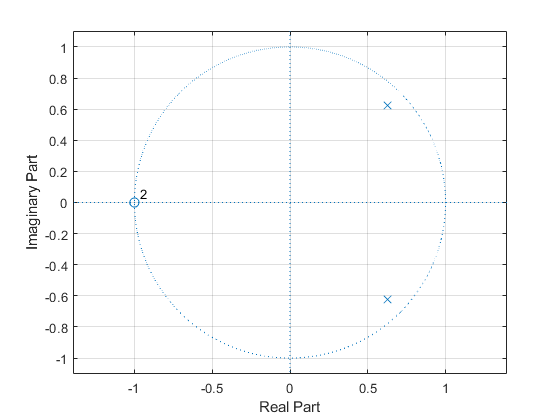

clc; close all; clear all;
%Q.2.2: zplane to show the pole-zero plot
%y[n]=1.25y[n-1]-0.78125y[n-2]+x[n]+2x[n-1]+x[n-2]
b = [1 2 1];                         % num coefficientas               
a = [1 -1.25 0.78125];               % den coefficientas 
zplane(b,a)
grid on

**(f)** Draw the magnitude response of the filter and verify the value of (*fm*) and BW from the magnitude response.

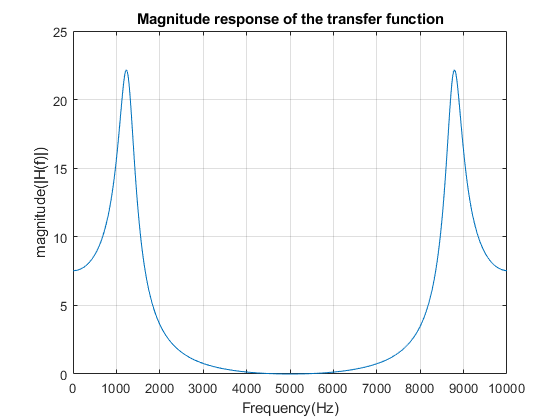

clc; close all; clear all;
b=[1 2 1]; 
a=[1 -1.25 0.78125];  
z=abs(freqz(b,a,512,'whole')); 
k=0:10000/511:10000;
plot(k,z)
title('Magnitude response of the transfer function');
xlabel('Frequency(Hz)');
ylabel('magnitude(|H(f)|)')
grid on

**(c)** Determine the frequency of the maximum magnitude (*fm*) of the filter

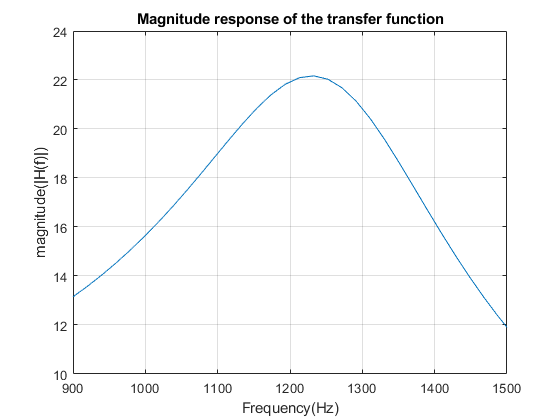

clc; close all; clear all;
b=[1 2 1]; 
a=[1 -1.25 0.78125];  
z=abs(freqz(b,a,512,'whole')); 
k=0:10000/511:10000;
plot(k,z)
title('Magnitude response of the transfer function');
xlabel('Frequency(Hz)');
ylabel('magnitude(|H(f)|)');
xlim ([900 1500]);
grid on